# Bioingeniería II - 2019-3

Ejercicio en clase

13 de marzo de 2020

Diana Carolina Diaz                Cod: 20151005010

Jeison Estiven García             Cod: 20151005015

Nicolas Rodríguez Daza         Cod: 20151005022

# Objetivo

Identificar las características eléctricas de algunas señales EMG capturadas con electrodos superficiales.

# Actividades Propuestas:

Organizados en grupos de tres personas, procedan a desarrollar las actividades consignadas a continuación. El desarrollo de cada actividad debe registrarse en este mismo archivo. Al final de la clase deben enviar este archivo (en formato mlx) junto con su versión en pdf al correo: hilopezc@udistrital.edu.co.

## Actividad 1

Realicen la carga en MATLAB de la señal EMG de prueba. Considerando que la frecuencia de muestreo es de 200Hz, muestren todos los canales en un `subplot` de ocho filas, marcando los ejes con las escalas temporales adecuadas.

% Consignen aquí las instrucciones respectivas
a=load('emgprueba.mat');
a=a.G1juan;
time=(1:length(a))*1/200;
figure('renderer','painters',"Position",[50 50 800 800 ])
for i=1:8
    subplot(8,1,i);
    superplot(time,a(:,i),strcat("canal :",num2str(i)),'tiempo (s)','',2);
end

## Actividad 2

Ahora, modifiquen la escala temporal para visualizar los potenciales de acción de las unidades motoras. ¿Se pueden identificar potenciales monofásicos, bifásicos o trifásicos? ¿Se pueden identificar los picos etiquetados como *turns*?

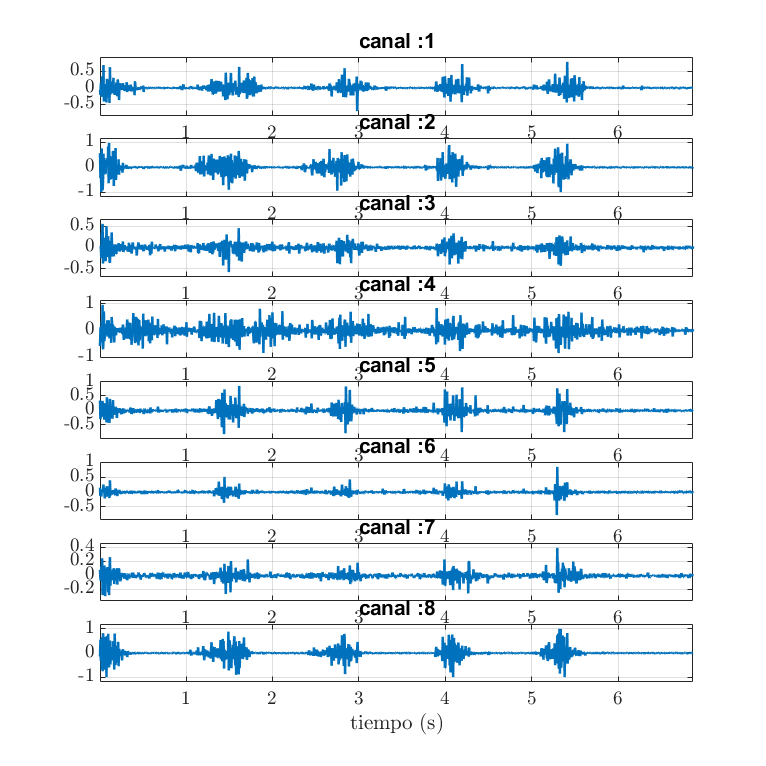

figure('renderer','painters',"Position",[50 50 800 800 ])

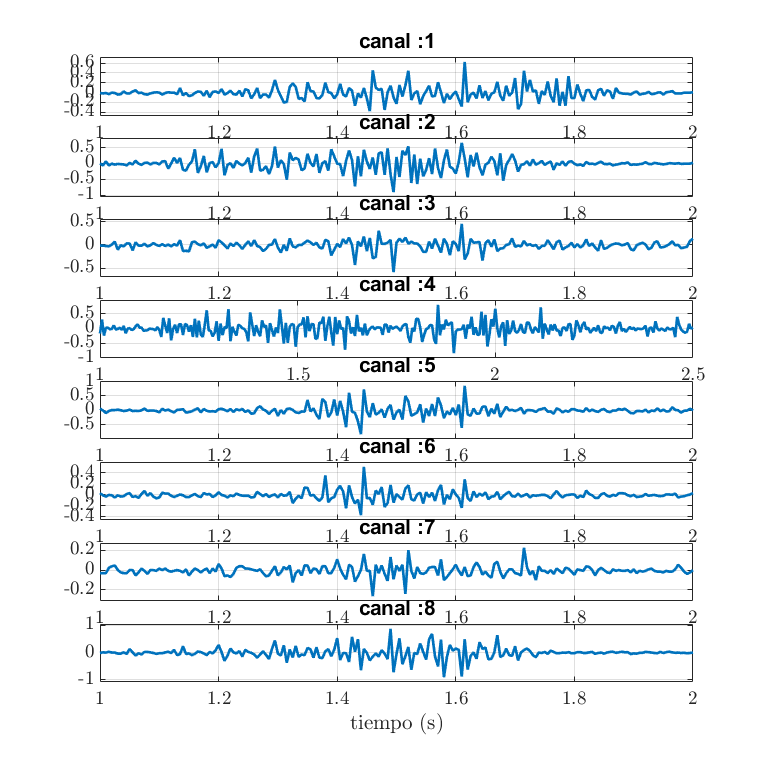

for i=1:8
    if i==4
    subplot(8,1,i);
    superplot(time(200:500),a(200:500,i),strcat("canal :",num2str(i)),'tiempo (s)','',2);
    else
        subplot(8,1,i);
        superplot(time(200:400),a(200:400,i),strcat("canal :",num2str(i)),'tiempo (s)','',2);
    end
end
n=8; %CANAL
figure('renderer','painters',"Position",[50 50 1500 300])
t1=time(200:400);
g1=a(200:400,n);

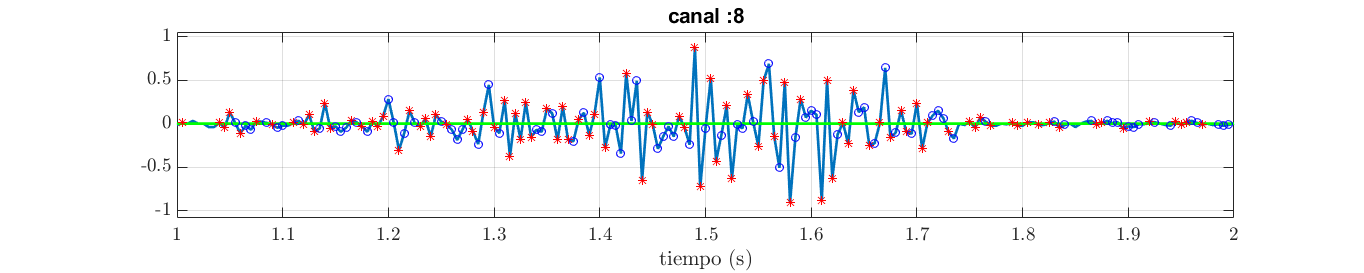

superplot(t1,g1,strcat("canal :",num2str(n)),'tiempo (s)','',2);
hold on
e0=zeros(length(t1),1);
plot(t1,e0,'g','lineWidth',2)
for e=1:1:length(t1)-1
    if (g1(e)<-0.0001 && g1(e+1)>0.0001) || (g1(e)>0.0001 && g1(e+1)<-0.0001)
       plot(t1(e+1),g1(e+1),'r*')
    end
    if g1(e)>0 && g1(e+1)>0 && abs(g1(e)-g1(e+1))>0.0001
       plot(t1(e+1),g1(e+1),'bo') 
    end
    if g1(e)<0 && g1(e+1)<0 && abs(g1(e)-g1(e+1))>0.0001
       plot(t1(e+1),g1(e+1),'bo')
    end
end

Siendo: 

- $'*'$ puntos en que ocurre un cambio de fase.

-  $'o'$ puntos en que tiene lugar un turn.

## Actividad 3

Utilicen la `fft` para obtener el espectro positivo de cada uno de los canales de la señal de prueba. ¿Cuánto es el ancho de banda de la señal capturada?

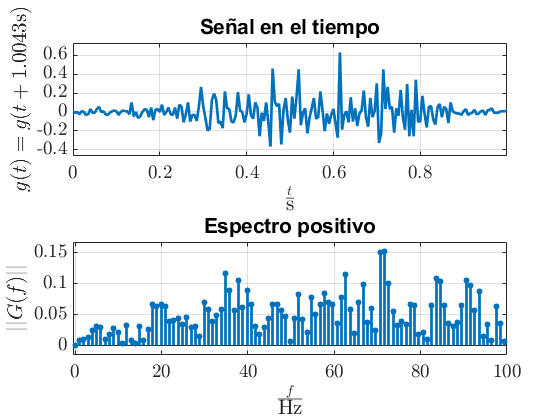

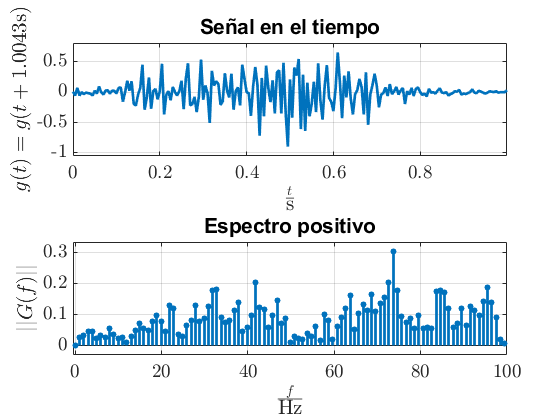

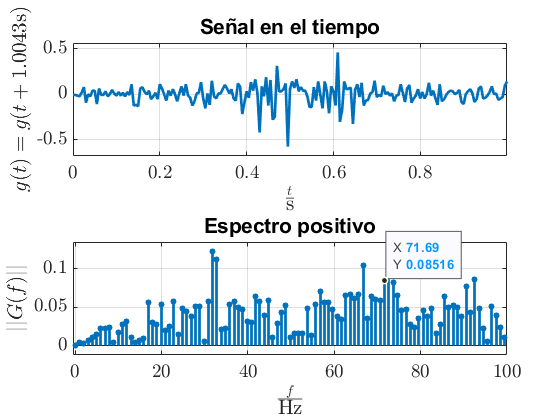

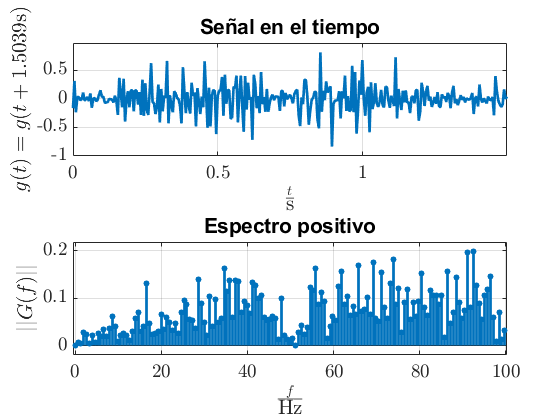

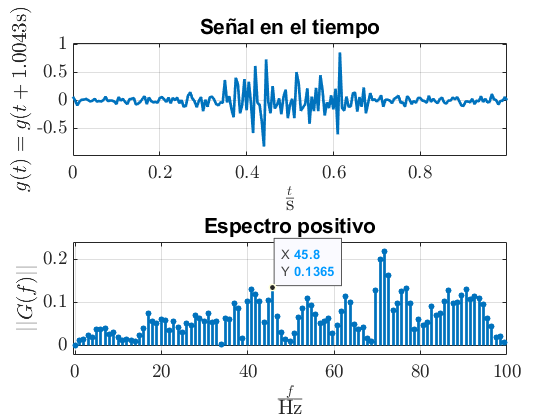

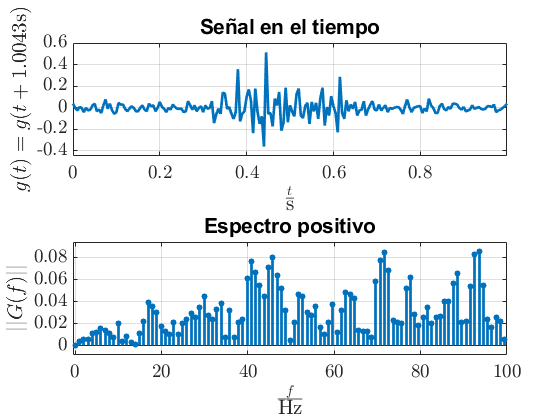

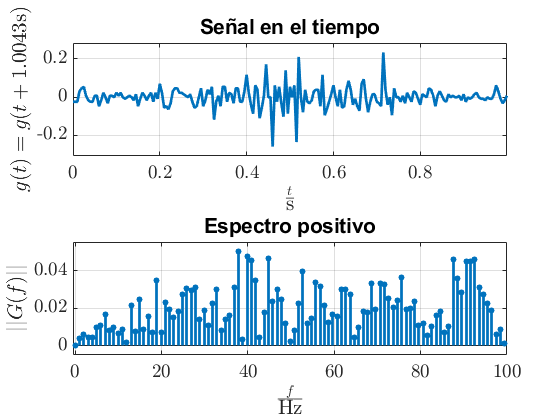

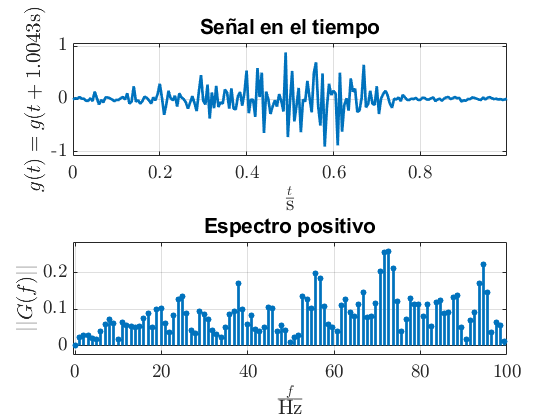

for i=1:8
    figure()
    if i==4
        rango=200:500;
        espectrofftJDR([time',a(:,i)],1,100,rango);
    else
        rango=200:400;
        espectrofftJDR([time',a(:,i)],1,100,rango);
    end 
end

# Conclusiones

2. Es posible identificar puntos en los cuales se registra cambios de fase o *turns*, sin embargo, debido a la proximidad de las fibras musculares encargadas del movimiento y por ende la superposición de los potenciales de acción de las unidades motoras, se dificulta discernir donde empieza un potencial de una fibra muscular y termina el potencial de la fibra vecina, por lo cual no se discrimina que potenciales son monofásicos, bifásicos o trifásicos.

3. Por medio de la gráfica de espectro en frecuencia de cada canal correspondiente a un electrodo de superficie se comprobó que el ancho de banda de cada canal es de alrededor 50 Hz, sin embargo la frecuencia central varía para cada electrodo en el gesto en que se captura la señal EMG, y estas frecuencias se encuentran distribuidas alrededor de los 100 Hz que a su vez constituye el espectro positivo de la señal EMG por lo cual se concluye que para esta señal particular el ancho de banda es de 100 Hz. 